# Lesson 7: Creating Complex Color Filters

## Creating Complex Color Filters

Let's test out new concatenation skills by creating a complex filter matching the specifications of the national flag of the United States of America (except without the 50 stars).  We'll once again use the `newFilter` function from the [Pixels to Pictures](https://www.mathworks.com/academia/highschool/courseware/pixels-to-pictures.html) toolbox to create each color stripe, and then use concatenation to stitch the pieces together.

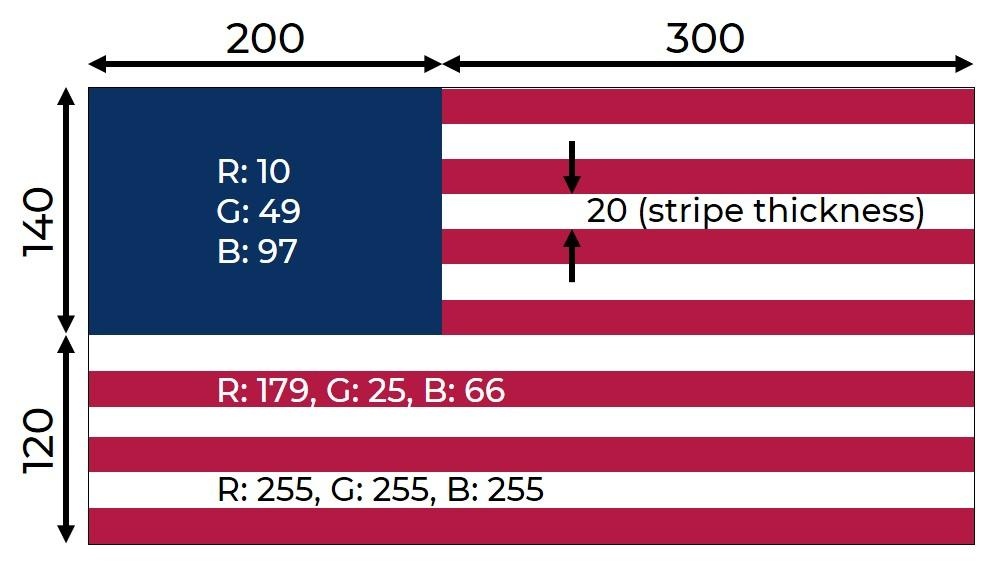

% Use the newFilter function to create the blue field
BF = newFilter(140,200,[10 49 97]);

% Use the newFilter function to create red and white short stripes
RS = newFilter(20,300,[179 25 66]);
WS = newFilter(20,300,[255 255 255]);
SS = [RS; WS; RS; WS; RS; WS; RS];  % vertically concatenate 7 short stripes

% Use the newFilter function to create red and white long stripes
RL = newFilter(20,500,[179 25 66]);
WL = newFilter(20,500,[255 255 255]);
LS = [WL; RL; WL; RL; WL; RL];  % vertically concatenate 6 short stripes

% Use square brackets and semicolons to concatenate filters pieces together
Flag1 = [BF SS; LS];

% Show concatenated filter
imshow(Flag1)

## Add Filter to an Image

Img = imread("TopOfNYC.jpg");  % read an image
sz  = size(Flag1);             % get size of filter
Img = imresize(Img,sz(1:2));   % resize image to match

Combo1 = Img + 0.5*Flag1;      % reduce filter intensity by half
imshow(Combo1)                 % display combined image/filter

## Use a Flag Image Instead

Recall our color filters are just the concatenation of single color images.  So, now that we've learned about concatenation, we could just use an image of a flag directly instead of creating a complex filter.

url = "https://cdn.britannica.com/33/4833-050-F6E415FE/" ...
    + "Flag-United-States-of-America.jpg";
Flag2 = imread(url);
Flag2 = imresize(Flag2,sz(1:2));  % resize to match image
imshow(Flag2)                     % display flag image

Combo2 = Img + 0.5*Flag2;         % reduce filter intensity by half
imshow(Combo2)                    % display combined image/filter